## **Visualisation des différentes configurations du robot pour suivre une trajectoire**

Ce code permet, après definition des variables, des longueurs des bras du robot, de la position desiree de l'effecteur, du nombre de solution souhaités affichées, et des butées de chaque articulation, de générer l'espace de travail du robot, puis de le visualiser dans les configurations possibles pour atteindre le point désiré par résolution de la cinmeatique inverse par la méthode variationnelle. 

### **Definition des variables**

% Définir les symboles pour les angles d'articulation
syms theta1 theta2 theta3 theta4;

% Définir les longueurs des bras
a1 = 2; % Longueur du premier bras
a2 = 3; % Longueur du deuxième bras
a3 = 2; % Longueur du troisième bras
a4 = 2; % Longueur du quatrieme bras
a5 = 2; % Longueur du cinquieme bras

theta1_min = -20;
theta1_max = 90;
theta2_min = -95;
theta2_max = 95;
theta3_min = -90;
theta3_max = 90;
theta4_min = -90;
theta4_max = 90;
theta5_min = -90;
theta5_max = 90;

% Stocker les valeurs dans la matrice butee
butee = [theta1_min, theta1_max; theta2_min, theta2_max; theta3_min, theta3_max; theta4_min, theta4_max; theta5_min, theta5_max];
% Enregistrement de la matrice dans un fichier .mat
save('butee.mat', 'butee');
% Convertir les limites des intervalles de degrés en radians
butee_rad = deg2rad(butee);

num_configurations = 1;


### Definition de la trajectoire

% Définir la trajectoire souhaitée (par exemple, un cercle)
num_points = 10;
radius = 8;
theta_traj = linspace(0, pi/3, num_points);
x_traj = radius * cos(theta_traj);
y_traj = radius * sin(theta_traj);
% Combiner les coordonnées x et y en une seule matrice de points de trajectoire
trajectory_points = [x_traj', y_traj'];
% Afficher les points de la trajectoire sous forme de tableau
disp('Points de la trajectoire :');

Points de la trajectoire :


fprintf('-------------------------------------\n');

-------------------------------------


fprintf('| Point  |      X     |      Y     |\n');

| Point  |      X     |      Y     |


fprintf('-------------------------------------\n');

-------------------------------------


for i = 1:num_points
    fprintf('|   %2d   |   %7.2f   |   %7.2f   |\n', i, x_traj(i), y_traj(i));
end

|    1   |      8.00   |      0.00   |
|    2   |      7.95   |      0.93   |
|    3   |      7.78   |      1.84   |
|    4   |      7.52   |      2.74   |
|    5   |      7.15   |      3.59   |
|    6   |      6.68   |      4.40   |
|    7   |      6.13   |      5.14   |
|    8   |      5.49   |      5.82   |
|    9   |      4.78   |      6.42   |
|   10   |      4.00   |      6.93   |


fprintf('--------------------------------------\n')

--------------------------------------


### Resolution IK après vérification de l'appartenance du point cible à l'espace de travail

Cette partie procède tout d'abord à une verification de l'appartenance du point désiré de l'effecteur à l'esapce de travail du robot. Si cela est vérifé on lance alors le calcul de cinématique inverse par la méthode variationnelle. 

Puis on affiche les solutions , d'abord en raidan et ensuite en degrès.

### Définition des variables 

% Initialiser une matrice pour stocker les résultats finaux
final_results = [];

% Paramètres pour d'ajustement du rayon
max_iterations = 1;
tolerance = 1;
% Vecteur pour stocker les rayons actualisés

### Resolution IK pour chaque points de la trajectoire après avoir vérifié si elle appartient à l'espace de travail

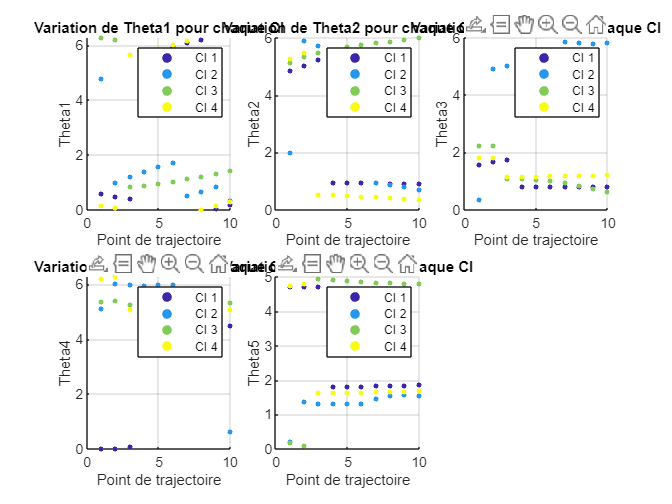

% Créer une nouvelle figure à l'extérieur de la boucle
figure;

% Initialiser un tableau pour stocker les couleurs uniques
unique_colors_map = containers.Map('KeyType', 'double', 'ValueType', 'double');
color_index = 1;

% Choisir une carte de couleurs
custom_colormap = parula(size(point1_solutions, 1));

% Boucle sur chaque angle d'articulation
for joint = 1:5
    % Créer un subplot pour chaque angle d'articulation
    subplot(2, 3, joint);
    
    % Titre de subplot
    title(['Variation de Theta', num2str(joint), ' pour chaque CI']);
    xlabel('Point de trajectoire');
    ylabel(['Theta', num2str(joint)]);
    hold on;
    
    % Boucle sur chaque ligne de point1_solutions
    for row = 1:size(point1_solutions, 1)  
        % Modifier theta_init avec les valeurs de la ligne actuelle de point1_solutions
        theta_init = point1_solutions(row, :);

        % Réinitialiser les valeurs initiales des angles précédents avec theta_init
        theta_prev = theta_init;

        % Initialiser la matrice finale
        final_results = [];

        % Itérer sur chaque point de la trajectoire
        for i = 1:num_points       
            % Utiliser les solutions précédentes comme points de départ pour les angles
            if i > 1
                % Pour les points suivants, utiliser les angles de la dernière solution
                theta_prev = final_results(final_results(:, 1) == i-1, 2:end);
            end

            % Initialiser le rayon avec le rayon d'origine
            current_radius = radius;

            % Calculer les coordonnées du point de la trajectoire avec le rayon actuel
            x_desired = current_radius * cos(theta_traj(i));
            y_desired = current_radius * sin(theta_traj(i));

            % Appeler la fonction de cinématique inverse pour trouver les solutions pour ce point
            all_solutions = find_inverse_kinematics(a1, a2, a3, a4, a5, x_desired, y_desired, num_configurations, theta_prev);

            % Ajouter une colonne pour le numéro du point de trajectoire
            point_numbers = repmat(i, size(all_solutions, 1), 1);
            all_solutions_with_point_numbers = [point_numbers, all_solutions];

            % Ajouter les résultats à la matrice finale
            final_results = [final_results; all_solutions_with_point_numbers];

            % Réinitialiser theta_prev avec les angles trouvés pour ce point
            theta_prev = all_solutions(end, 2:end);

        end
        
        % Tracer les valeurs de l'angle de l'articulation pour chaque ligne de point1_solutions
        % sur le même graphique avec une couleur différente pour chaque ligne
        scatter(final_results(:,1), final_results(:,joint+1), 10, custom_colormap(row, :), 'filled', 'DisplayName', ['CI ', num2str(row)]);
        hold on;
    end
  
    % Afficher la légende pour chaque subplot
    legend('show');
    grid on;
end

### Affichage des résultats de cinématique inverse

% Afficher le rayon actualisé
fprintf('Rayon actualisé pour la trajectoire :\n');

Rayon actualisé pour la trajectoire :


disp(adjusted_radius);

     8     8     8     8     8     8     8     8     8     8



    
% Afficher la trajectoire avec le rayon ajusté
x_traj_adjusted = adjusted_radius .* cos(theta_traj);
y_traj_adjusted = adjusted_radius .* sin(theta_traj);
% Combiner les coordonnées x et y en une seule matrice de points de trajectoire
trajectory_points = [x_traj_adjusted', y_traj_adjusted'];
% Afficher les points de la trajectoire sous forme de tableau
disp('Points de la trajectoire ajustée :');

Points de la trajectoire ajustée :


fprintf('-------------------------------------------------\n');

-------------------------------------------------


fprintf('| Point  |      X     |      Y     |\n');

| Point  |      X     |      Y     |


fprintf('-------------------------------------------------\n');

-------------------------------------------------


for i = 1:num_points
    fprintf('|   %2d   |   %7.2f   |   %7.2f   |\n', i, x_traj_adjusted(i), y_traj_adjusted(i));
end

|    1   |      8.00   |      0.00   |
|    2   |      7.95   |      0.93   |
|    3   |      7.78   |      1.84   |
|    4   |      7.52   |      2.74   |
|    5   |      7.15   |      3.59   |
|    6   |      6.68   |      4.40   |
|    7   |      6.13   |      5.14   |
|    8   |      5.49   |      5.82   |
|    9   |      4.78   |      6.42   |
|   10   |      4.00   |      6.93   |


fprintf('-------------------------------------------------\n')

-------------------------------------------------




% Afficher le tableau final
fprintf('-----------------------------------------------------------------------------\n');

-----------------------------------------------------------------------------


fprintf('| Point  | Theta1   | Theta2   | Theta3   | Theta4   | Theta5   | X_calculé | Y_calculé |\n');

| Point  | Theta1   | Theta2   | Theta3   | Theta4   | Theta5   | X_calculé | Y_calculé |


fprintf('-----------------------------------------------------------------------------\n');

-----------------------------------------------------------------------------


for row = 1:size(final_results, 1)
    fprintf('|   %2d   | %8.2f | %8.2f | %8.2f | %8.2f | %8.2f | %9.2f | %9.2f |\n', final_results(row, :));
end

|    1   |     0.15 |     5.29 |     1.80 |     6.19 |     4.76 |      8.00 |     -0.00 |
|    2   |     0.08 |     5.48 |     1.82 |     6.27 |     4.80 |      7.95 |      0.93 |
|    3   |     5.64 |     0.53 |     1.15 |     5.08 |     1.63 |      7.78 |      1.84 |
|    4   |     5.76 |     0.52 |     1.16 |     5.08 |     1.63 |      7.52 |      2.74 |
|    5   |     5.89 |     0.50 |     1.17 |     5.08 |     1.63 |      7.15 |      3.59 |
|    6   |     6.02 |     0.47 |     1.18 |     5.08 |     1.64 |      6.68 |      4.40 |
|    7   |     6.16 |     0.44 |     1.19 |     5.08 |     1.65 |      6.13 |      5.14 |
|    8   |     0.02 |     0.41 |     1.20 |     5.08 |     1.66 |      5.49 |      5.82 |
|    9   |     0.16 |     0.37 |     1.21 |     5.08 |     1.68 |      4.78 |      6.42 |
|   10   |     0.29 |     0.34 |     1.21 |     5.08 |     1.69 |      4.00 |      6.93 |


fprintf('-----------------------------------------------------------------------------\n');

-----------------------------------------------------------------------------


### Visualiser le robot

% Afficher la trajectoire
figure;
plot(x_traj, y_traj, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Trajectoire à suivre' );
axis equal; % Pour que l'échelle des axes soit égale
xlabel('X');
ylabel('Y');
title('Trajectoire');
grid on;
hold on;

### Affichage de l'espace de travail : 

- liste pour **stocker les coordonnees atteignables,**

- definition de l**'echantillon d'angles testés et du pas**

% Initialiser une liste pour stocker les coordonnées atteignables
reachable_points = [];

% % Définir la grille d'angles d'articulation
theta1_range = linspace(butee_rad(1, 1), butee_rad(1, 2), 6);
theta2_range = linspace(butee_rad(2, 1), butee_rad(2, 2), 6);
theta3_range = linspace(butee_rad(3, 1), butee_rad(3, 2), 6);
theta4_range = linspace(butee_rad(4, 1), butee_rad(4, 2), 6);
theta5_range = linspace(butee_rad(5, 1), butee_rad(5, 2), 6);
% % Nombre de pas pour chaque articulation
% step_angle = 15; % Espacement entre chaque angle en degrés

- **calcul des coordonnees atteignables** pour chaque combinaison d'angles possibles de l'echantillon, par **cinematique directe**

% Calculer les coordonnées atteignables pour chaque combinaison d'angles
for i = 1:length(theta1_range)
    for j = 1:length(theta2_range)
        for k = 1:length(theta3_range)
            for l = 1:length(theta4_range)
                for m = 1:length(theta5_range)
                    % Calculer les coordonnées de l'effecteur
                    x = a1 * cos(theta1_range(i)) + a2 * cos(theta1_range(i) + theta2_range(j)) + a3 * cos(theta1_range(i) + theta2_range(j) + theta3_range(k)) + a4 * cos(theta1_range(i) + theta2_range(j) + theta3_range(k) + theta4_range(l)) + a5 * cos(theta1_range(i) + theta2_range(j) + theta3_range(k) + theta4_range(l) + theta5_range(m));
                    y = a1 * sin(theta1_range(i)) + a2 * sin(theta1_range(i) + theta2_range(j)) + a3 * sin(theta1_range(i) + theta2_range(j) + theta3_range(k)) + a4 * sin(theta1_range(i) + theta2_range(j) + theta3_range(k) + theta4_range(l)) + a5 * sin(theta1_range(i) + theta2_range(j) + theta3_range(k) + theta4_range(l) + theta5_range(m));
                     % Ajouter les coordonnées à la liste
                    reachable_points = [reachable_points; x, y];
                end
            end
        end
    end
end

points_atteign = [reachable_points(:, 1), reachable_points(:, 2)];


- affichage des **contours de l'espace de travail**

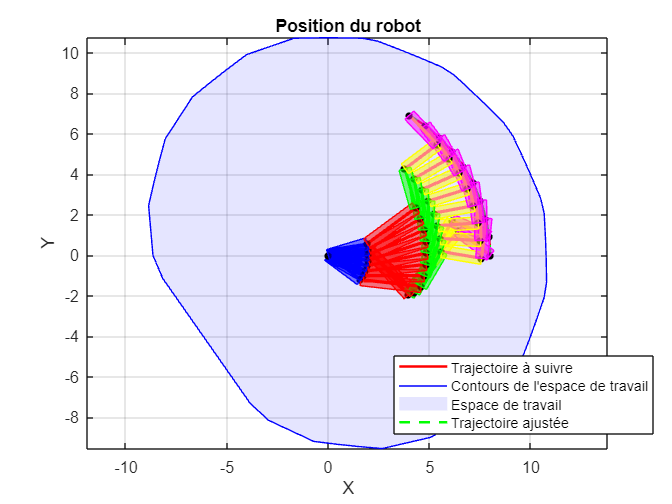

% % Calculer les contours convexes du nuage de points avec une méthode plus précise
K = convhull(points_atteign);

% % Tracer les contours de l'espace de travail
plot(points_atteign(K, 1), points_atteign(K, 2), 'b', 'LineWidth', .5, 'DisplayName', 'Contours de l''espace de travail');
fill(points_atteign(K, 1), points_atteign(K, 2), 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'none', 'DisplayName', 'Espace de travail');

% Mettre à jour le graphique
title('Position du robot' );
xlabel('X');
ylabel('Y');
axis equal; % Assure que les proportions X/Y sont égales
grid on;
legend show;
legend("Position", [0.58731,0.15829,0.38571,0.11905])

hold on;% Tracer la nouvelle trajectoire avec le rayon ajusté sur la même figure
hold on;
plot(x_traj_adjusted, y_traj_adjusted, 'g--', 'LineWidth', 1.5, 'DisplayName', 'Trajectoire ajustée');
hold on;
% Mettre à jour le graphique
legend show;

% Enregistrer les solutions dans un fichier
save('solutionstraj.mat', 'final_results');

hold on;

for i = 1:size(final_results, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = final_results(i, 2);
    theta2 = final_results(i, 3);
    theta3 = final_results(i, 4);
    theta4 = final_results(i, 5);
    theta5 = final_results(i, 6);

    % Calcul des positions des articulations du robot avec les valeurs des angles d'articulation calculées
    O = [0, 0]; % Position de l'origine
    A = [a1*cos(theta1), a1*sin(theta1)]; % Position de l'articulation A
    B = A + [a2*cos(theta1+theta2), a2*sin(theta1+theta2)]; % Position de l'articulation B
    C = B + [a3*cos(theta1+theta2+theta3), a3*sin(theta1+theta2+theta3)]; % Position de l'articulation C (extrémité de l'effecteur)
    D = C + [a4*cos(theta1+theta2+theta3+theta4), a4*sin(theta1+theta2+theta3+theta4)]; % Position de l'articulation C (extrémité de l'effecteur)
    E = D + [a5*cos(theta1+theta2+theta3+theta4+theta5), a5*sin(theta1+theta2+theta3+theta4+theta5)]; % Position de l'articulation C (extrémité de l'effecteur)

     % Tracer le robot pour cette configuration
    plot([O(1), A(1)], [O(2), A(2)], 'LineWidth', 2, 'Color', color_segment_OA, 'HandleVisibility', 'off'); % Segment OA
    plot([A(1), B(1)], [A(2), B(2)], 'LineWidth', 2, 'Color', color_segment_AB, 'HandleVisibility', 'off'); % Segment AB
    plot([B(1), C(1)], [B(2), C(2)], 'LineWidth', 2, 'Color', color_segment_BC, 'HandleVisibility', 'off'); % Segment BC
    plot([C(1), D(1)], [C(2), D(2)], 'LineWidth', 2, 'Color', color_segment_CD, 'HandleVisibility', 'off'); % Segment CD
    plot([D(1), E(1)], [D(2), E(2)], 'LineWidth', 2, 'Color', color_segment_DE, 'HandleVisibility', 'off'); % Segment DE
    scatter([O(1), A(1), B(1), C(1), D(1), E(1)], [O(2), A(2), B(2), C(2), D(2), E(2)], 20, 'k', 'filled', 'HandleVisibility', 'off'); % Marques pour les articulations
    % Ajouter des rectangles autour des segments
    rectWidth = 0.3; % Ajustez cette valeur selon vos besoins
    drawSegmentRectangle(O, A, rectWidth, 'b');
    drawSegmentRectangle(A, B, rectWidth, 'r');
    drawSegmentRectangle(B, C, rectWidth, 'g');
    drawSegmentRectangle(C, D, rectWidth, 'y');
    drawSegmentRectangle(D, E, rectWidth, 'm');
    % Mettre en pause pour une durée appropriée
    pause(0.1); % Changer cette valeur pour ajuster la vitesse de l'animation
end

### Variation de theta1 pour chaque solution. Tous les points avec le même numéro de point auront la même couleur dans le graphique.

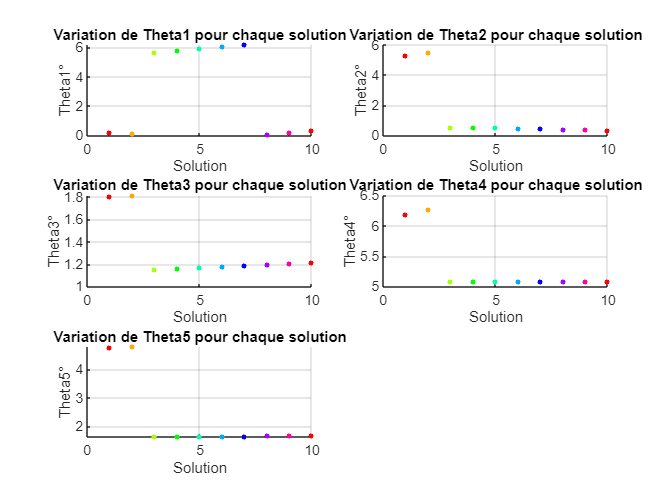


figure;
% Créer un tableau de hachage pour mapper chaque numéro de point à une couleur
unique_colors_map = containers.Map('KeyType', 'double', 'ValueType', 'double');
color_index = 1;

for i = 1:size(final_results, 1)
    point_number = final_results(i, 1); % Numéro de point
    if ~isKey(unique_colors_map, point_number)
        unique_colors_map(point_number) = color_index; % Assigner une nouvelle couleur pour chaque nouveau numéro de point
        color_index = color_index + 1;
    end
end

% Convertir les angles en degrés et ajuster les angles à l'intervalle [-180, 180]
final_results_deg = final_results(:, 2:6);
final_results_deg = mod(final_results_deg + 180, 360) - 180;

% Définir le nombre de lignes et de colonnes pour la grille
num_rows = 3; % Modifier le nombre de lignes selon le nombre de joints
num_cols = 2; % Nombre de colonnes pour afficher les graphiques

% Créer une nouvelle figure
figure;

% Boucle sur chaque angle d'articulation
for joint = 1:5
    % Définir la position du subplot dans la grille
    subplot(num_rows, num_cols, joint);
    
    % Boucle sur chaque solution
    for i = 1:size(final_results, 1)
        point_number = final_results(i, 1); % Numéro de point
        color_index = unique_colors_map(point_number); % Récupérer l'index de couleur pour ce numéro de point

        % Définir la couleur en fonction de l'index récupéré
        color = hsv2rgb([(color_index-1)/(size(unique_colors_map, 1)-1), 1, 1]); % Utiliser l'espace colorimétrique HSV pour obtenir des couleurs distinctes

        % Tracer le point avec la couleur définie
        scatter(i, final_results_deg(i, joint), 10, color, 'filled'); % Vous pouvez ajuster la taille du point (50) selon vos préférences
        hold on;
    end

    % Titre et étiquettes des axes
    title(['Variation de Theta', num2str(joint), ' pour chaque solution']);
    xlabel('Solution');
    ylabel(['Theta', num2str(joint), '°']);
    grid on;
end

### Variation de theta pour chaque solution avec une couleur pour chaque point de la trajectoire a suivre puis une forme pour chaque theta

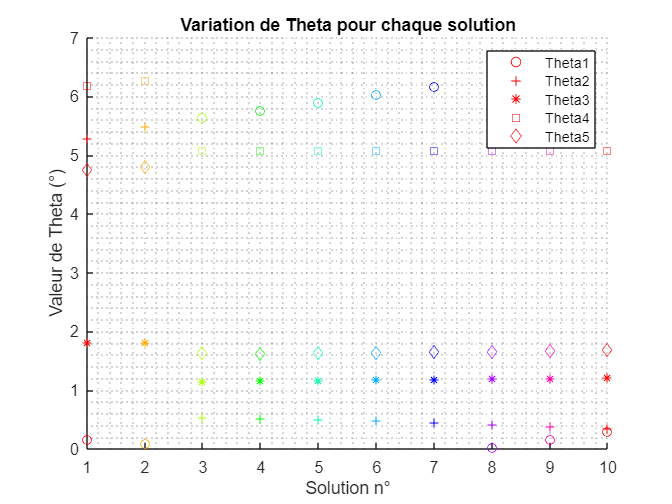


% Créer un tableau de hachage pour mapper chaque numéro de point à une couleur
unique_colors_map = containers.Map('KeyType', 'double', 'ValueType', 'double');
color_index = 1;

for i = 1:size(final_results, 1)
    point_number = final_results(i, 1); % Numéro de point
    if ~isKey(unique_colors_map, point_number)
        unique_colors_map(point_number) = color_index; % Assigner une nouvelle couleur pour chaque nouveau numéro de point
        color_index = color_index + 1;
    end
end

% Convertir les angles en degrés et ajuster les angles à l'intervalle [-180, 180]
final_results_deg = final_results(:, 2:6);
final_results_deg = mod(final_results_deg + 180, 360) - 180;

% Créer une nouvelle figure
figure;

% Boucle sur chaque solution
for i = 1:size(final_results, 1)
    point_number = final_results(i, 1); % Numéro de point
    
    % Récupérer l'index de couleur pour ce numéro de point
    color_index = unique_colors_map(point_number);

    % Définir la couleur en fonction de l'index récupéré
    color = hsv2rgb([(color_index-1)/(size(unique_colors_map, 1)-1), 1, 1]);

    % Tracer le point avec la couleur définie et une forme différente pour chaque valeur de theta
    for joint = 1:5
        % Choisir la forme de marqueur en fonction de la valeur de theta
        switch joint
            case 1
                marker = 'o';
            case 2
                marker = '+';
            case 3
                marker = '*';
            case 4
                marker = 's';
            case 5
                marker = 'd';
        end

        % Tracer le point avec la couleur définie et la forme de marqueur appropriée
        scatter(i, final_results_deg(i, joint), 30, color, marker);
        hold on;
    end
end

% Titre et étiquettes des axes
title('Variation de Theta pour chaque solution');
xlabel('Solution n°');
ylabel('Valeur de Theta (°)');

% Légende
legend('Theta1', 'Theta2', 'Theta3', 'Theta4', 'Theta5');

% Afficher la grille
grid minor;

function in_workspace = point_in_workspace(x, y, points_atteign, K)
    % Vérifie si le point (x, y) est dans l'espace de travail du robot
    in_workspace = inpolygon(x, y, points_atteign(K, 1), points_atteign(K, 2));
end

function drawSegmentRectangle(startPoint, endPoint, rectWidth, color)
    % Calcule la longueur et l'angle du segment
    segmentLength = norm(endPoint - startPoint);
    segmentAngle = atan2(endPoint(2) - startPoint(2), endPoint(1) - startPoint(1));
    
    % Calcule les coordonnées des coins du rectangle
    dx = rectWidth * cos(segmentAngle + pi/2);
    dy = rectWidth * sin(segmentAngle + pi/2);
    rectPoints = [startPoint(1) - dx, startPoint(2) - dy;
                  startPoint(1) + dx, startPoint(2) + dy;
                  endPoint(1) + dx, endPoint(2) + dy;
                  endPoint(1) - dx, endPoint(2) - dy;
                  startPoint(1) - dx, startPoint(2) - dy];
    
    % Trace le rectangle
    fill(rectPoints(:, 1), rectPoints(:, 2), color, 'EdgeColor', color, 'FaceAlpha', 0.5, 'HandleVisibility', 'off');
end

function [all_solutions] = find_inverse_kinematics(a1, a2, a3, a4, a5, x_desired, y_desired, num_configurations, theta_prev)

    % Définir les angles d'articulation
    syms theta1 theta2 theta3 theta4 theta5;

    % Définir une tolérance et un nombre maximum d'itérations
    tolerance = 0.0000001;
    max_iterations = 100;
    
    % Initialiser une liste pour stocker les configurations atteignables
    all_solutions = [];
    
    % Recherche des configurations
    while size(all_solutions, 1) < num_configurations
        
        % Initialiser les angles d'articulation avec les valeurs précédentes
        theta1 = theta_prev(1);
        theta2 = theta_prev(2);
        theta3 = theta_prev(3);
        theta4 = theta_prev(4);
        theta5 = theta_prev(5);

        % Boucle d'itération pour trouver les angles d'articulation
        for i = 1:max_iterations
            % Calculer les équations directes de cinématique directe
            x = a1*cos(theta1) + a3*cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a2*cos(theta1)*cos(theta2) - a2*sin(theta1)*sin(theta2) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)))) + a4*cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)));
            y = a1*sin(theta1) + a3*cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a3*sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + a2*cos(theta1)*sin(theta2) + a2*cos(theta2)*sin(theta1) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))) + a4*cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)))) + a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)));
          
            % Calculer l'erreur de position
            error_x = x_desired - x;
            error_y = y_desired - y;
            error = [error_x; error_y];

            % Calculer les dérivées partielles
            dx_dtheta1 = -a1*sin(theta1) - a3*cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) - a2*sin(theta1)*sin(theta2) - a2*cos(theta1)*cos(theta2) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
            dx_dtheta2 = -a3*cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a2*cos(theta1)*cos(theta2) - a2*sin(theta1)*sin(theta2) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
            dx_dtheta3 = a3*sin(theta3)*(sin(theta1)*sin(theta2) - cos(theta1)*cos(theta2)) + a4*sin(theta4)*(sin(theta1)*sin(theta2) - cos(theta1)*cos(theta2)) + a5*sin(theta5)*(sin(theta1)*sin(theta2) - cos(theta1)*cos(theta2));
            dx_dtheta4 = -a4*sin(theta4)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a5*sin(theta5)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2));
            dx_dtheta5 = -a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) - sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))));
    
            dy_dtheta1 = a1*cos(theta1) + a3*cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a3*sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + a2*cos(theta2)*sin(theta1) + a2*cos(theta1)*sin(theta2) + a4*cos(theta4)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))) + a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
            dy_dtheta2 = a3*cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a3*sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a2*sin(theta1)*sin(theta2) - a2*cos(theta1)*cos(theta2) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
            dy_dtheta3 = - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a4*sin(theta4)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a5*sin(theta5)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1));
            dy_dtheta4 = - a4*sin(theta4)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) - a5*sin(theta5)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1));
            dy_dtheta5 = a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) - sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) + sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)))));

            % Construire la Jacobienne
            J = [dx_dtheta1, dx_dtheta2, dx_dtheta3, dx_dtheta4, dx_dtheta5; 
                 dy_dtheta1, dy_dtheta2, dy_dtheta3, dy_dtheta4, dy_dtheta5];
    
            % Vérifier la convergence
            if norm(error) < tolerance
                % Stocker la solution
                all_solutions = [all_solutions; [theta1, theta2, theta3, theta4, theta5, x, y]];
                break;
            end

            % Calculer la variation des angles d'articulation
            delta_theta = pinv(J) * error;
    
            % Mise a jour des les angles d'articulation
            theta1 = theta1 + delta_theta(1);
            theta2 = theta2 + delta_theta(2);
            theta3 = theta3 + delta_theta(3);
            theta4 = theta4 + delta_theta(4);
            theta5 = theta5 + delta_theta(5);

            % Mettre à jour les angles d'articulation précédents pour le prochain point de trajectoire
            theta_prev = [theta1, theta2, theta3, theta4, theta5];
            
            % Maintien des angles entre 0 et 2*pi
            theta1 = mod(theta1, 2*pi);
            theta2 = mod(theta2, 2*pi);
            theta3 = mod(theta3, 2*pi);
            theta4 = mod(theta4, 2*pi);
            theta5 = mod(theta5, 2*pi);
        end
    end
end
